clearvars
close all
clc

osrm_data_sp = load('output_data\osrm_output_with_speed.mat').out;
aug_data = load('output_data\aug_output2.mat').aug_data;
segments = load('input_data\osm.mat').osm;
markers = load('input_data\markers.mat').markers;
% adding distance from origin column to aug_out
[~,b] = ismember(aug_data.segment_id,segments.segment_id);
aug_data.distance_from_start = segments.distance_from_start(b);

corridor_length = 1e-3 * max(sum(segments(segments.dir==2,:).calc_length) , sum(segments(segments.dir==1,:).calc_length));
osrm_data_sp.Properties.VariableNames{10} = 'dir';
osrm_data_sp.Properties.VariableNames{11} = 'segment_id';
aug_data.Properties.VariableNames{2} = 'time';
osrm_data_sp.Properties.VariableNames{4} = 'time';

aux_segments = unique(aug_data.segment_id);
filter = NaN(size(aug_data,1),1);
for i=1:1:length(aux_segments)
    filter(aug_data.segment_id == aux_segments(i)) = isoutlier(aug_data(aug_data.segment_id == aux_segments(i),:).speed,'quartiles');
end
aug_data.filter = ~logical(filter);
size(aug_data,1)

ans = 116188

sum(filter)

ans = 2750


aux_segments = unique(osrm_data_sp.segment_id);
filter = NaN(size(osrm_data_sp,1),1);
for i=1:1:length(aux_segments)
    filter(osrm_data_sp.segment_id == aux_segments(i)) = isoutlier(osrm_data_sp(osrm_data_sp.segment_id == aux_segments(i),:).speed,'quartiles');
end
osrm_data_sp.filter = ~logical(filter);
size(osrm_data_sp,1)

ans = 118063

sum(filter)

ans = 4259

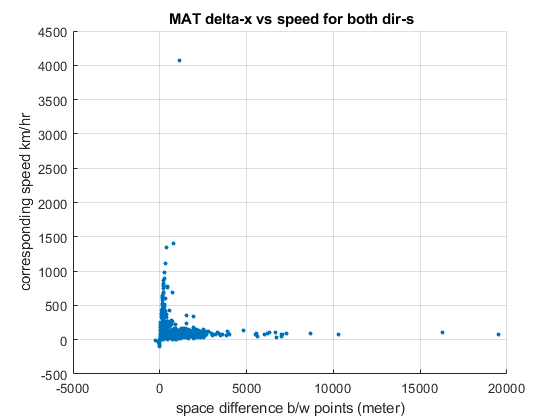

scatter(osrm_data_sp.space_distance,osrm_data_sp.speed,10,'filled')
xlabel('space difference b/w points (meter)')
ylabel('corresponding speed km/hr')
grid on
title(' MAT delta-x vs speed for both dir-s')

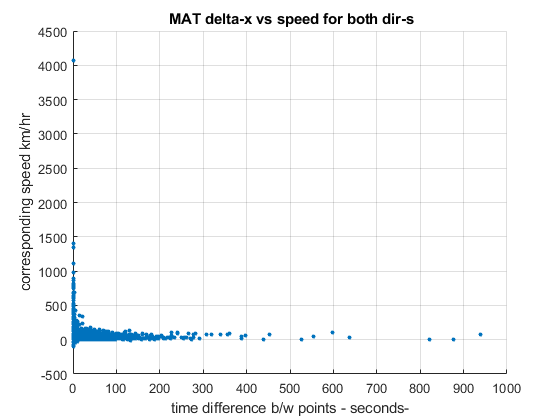

scatter(osrm_data_sp.time_distance * 60 * 60,osrm_data_sp.speed,10,'filled')
xlabel('time difference b/w points - seconds-')
ylabel('corresponding speed km/hr')
grid on
title(' MAT delta-x vs speed for both dir-s')

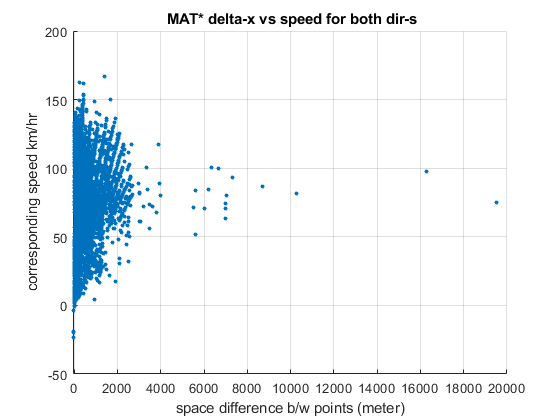


scatter(osrm_data_sp(osrm_data_sp.filter,:).space_distance,osrm_data_sp(osrm_data_sp.filter,:).speed,10,'filled')
xlabel('space difference b/w points (meter)')
ylabel('corresponding speed km/hr')
grid on
title(' MAT* delta-x vs speed for both dir-s')

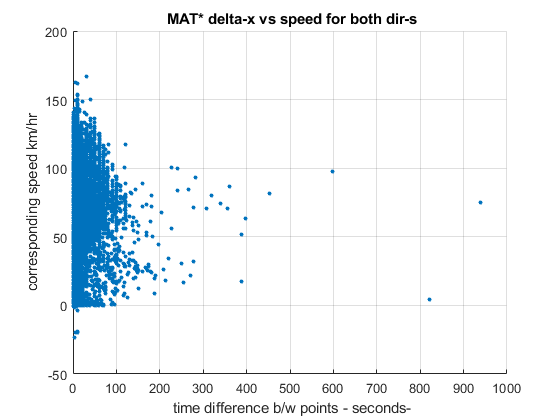


scatter(osrm_data_sp(osrm_data_sp.filter,:).time_distance * 60 * 60,osrm_data_sp(osrm_data_sp.filter,:).speed,10,'filled')
xlabel(' time difference b/w points - seconds-')
ylabel('corresponding speed km/hr')
grid on
title(' MAT* delta-x vs speed for both dir-s')

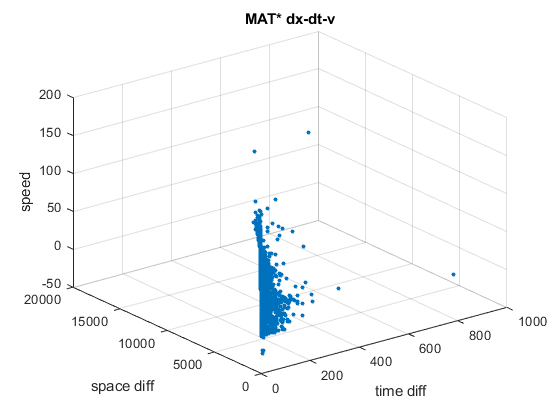


scatter3(osrm_data_sp(osrm_data_sp.filter,:).time_distance * 60 * 60,osrm_data_sp(osrm_data_sp.filter,:).space_distance,osrm_data_sp(osrm_data_sp.filter,:).speed,10,'filled')
xlabel('time diff')
ylabel('space diff')
zlabel('speed')
grid on
title('MAT* dx-dt-v')